clear
load data5.mat
n=length(data.CzasLokalnyUTC0100)

n = 6960

data.CzasLokalnyUTC0100(1:4)

ans = 4×1 datetime array
   15.09.2025 12:00:00
   15.09.2025 12:01:00
   15.09.2025 12:02:00
   15.09.2025 12:03:00


data.CzasLokalnyUTC0100(n-3:n)

ans = 4×1 datetime array
   20.09.2025 07:56:00
   20.09.2025 07:57:00
   20.09.2025 07:58:00
   20.09.2025 07:59:00


We observe fs of 60s

From time vector:

T=60; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Kompresor1=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;



TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Wlot=0.1*data.TemperaturaSterujca;


X=[Kompresor1,StanCzujnikaZamkniecia,...
    TemperaturaOtoczenia,Wlot]';

t=T*(1:n);
size(X)

ans =            4        6960


[dataWithoutNans,nan_indices]  = GetRidOfNans(X);
find(nan_indices,~0)


ans =

  0×1 empty double column vector



no nans

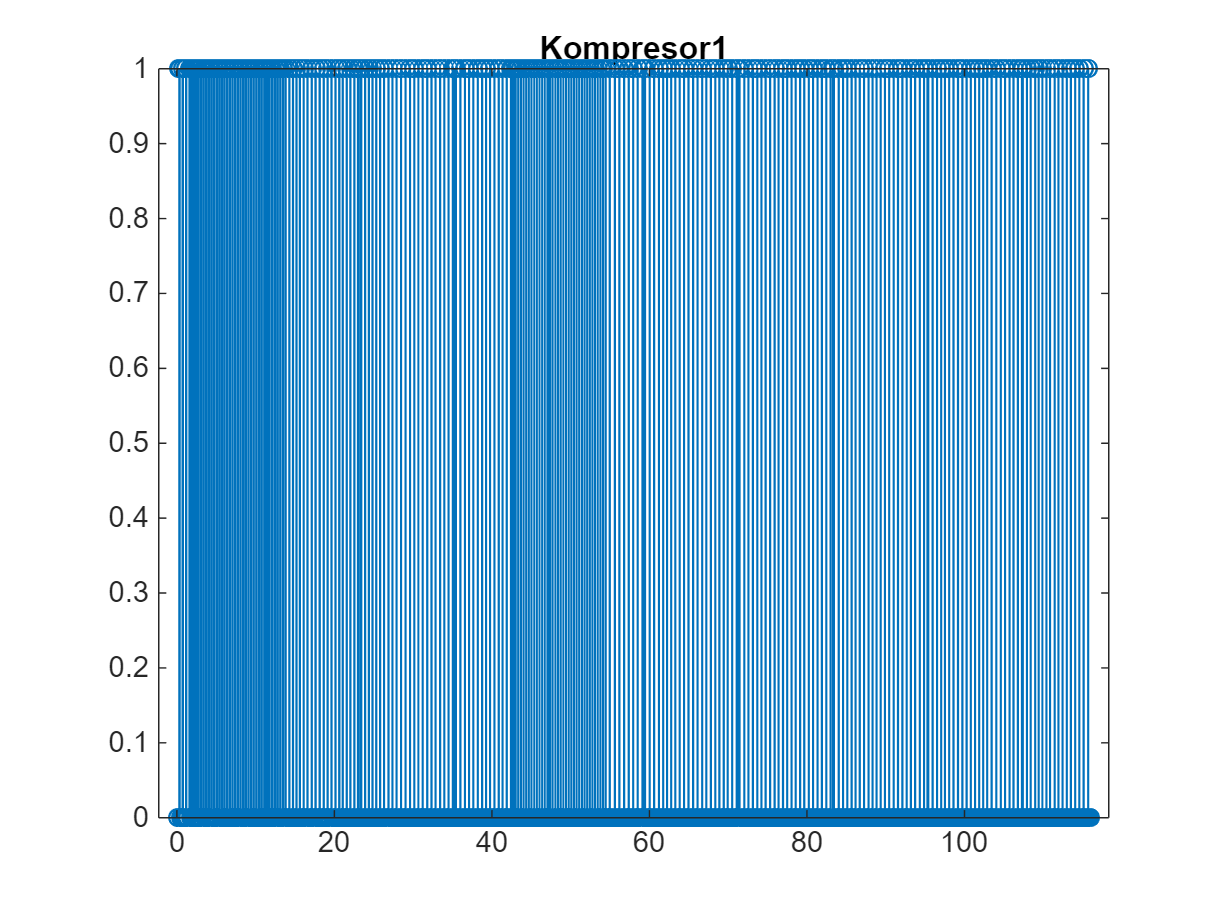

stem(t./(60*60),X(1,:))
title('Kompresor1')

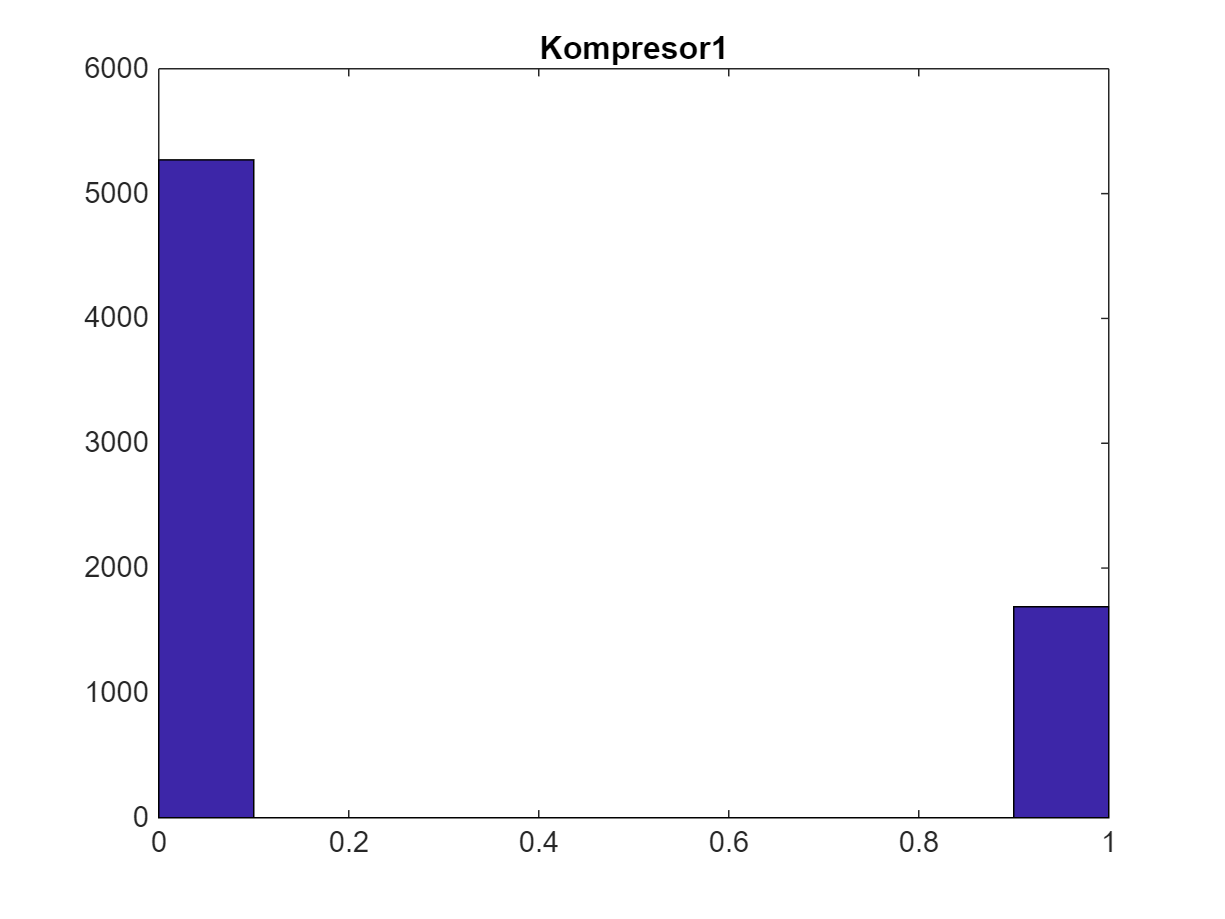

hist(X(1,:))
title('Kompresor1')

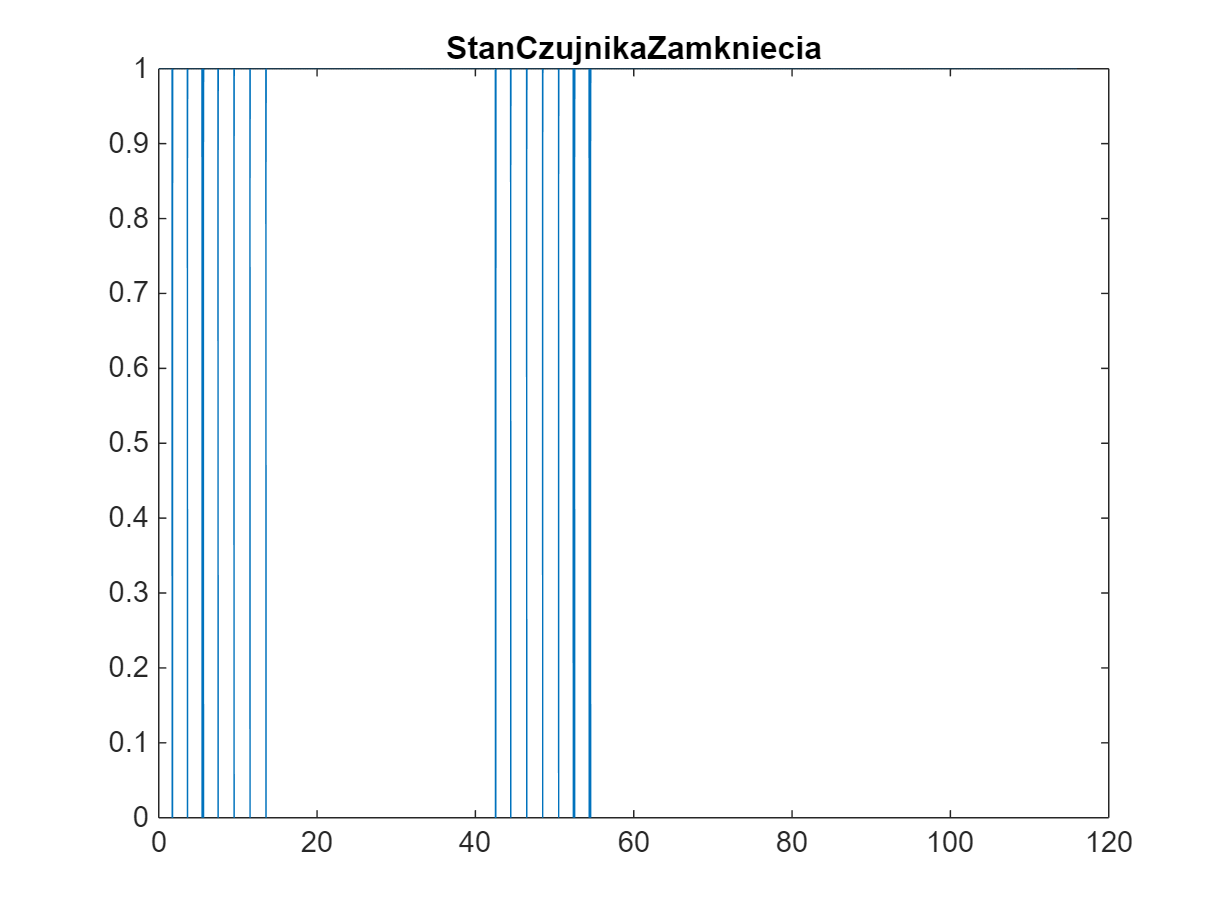

plot(t/(60*60),X(2,:))
title('StanCzujnikaZamkniecia')

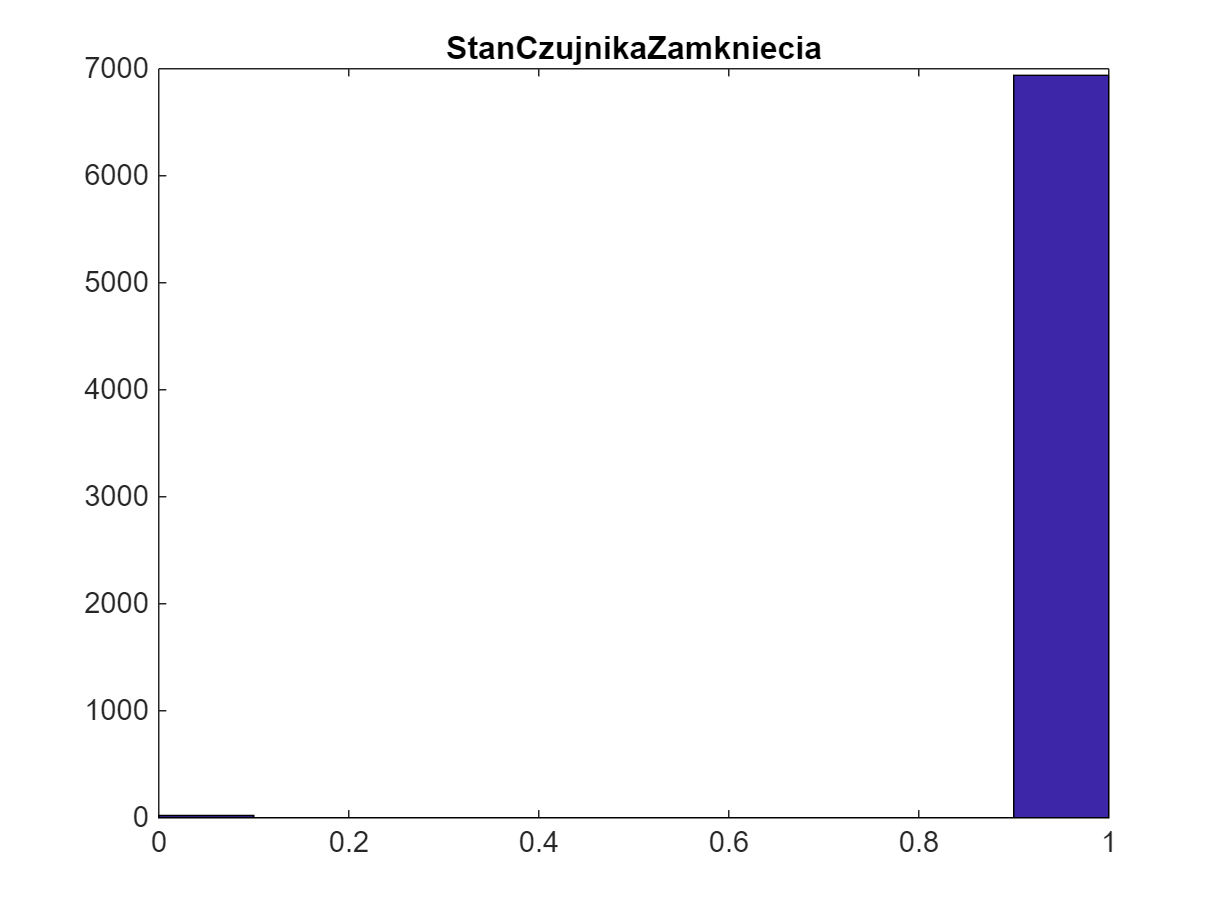

hist(X(2,:))
title('StanCzujnikaZamkniecia')

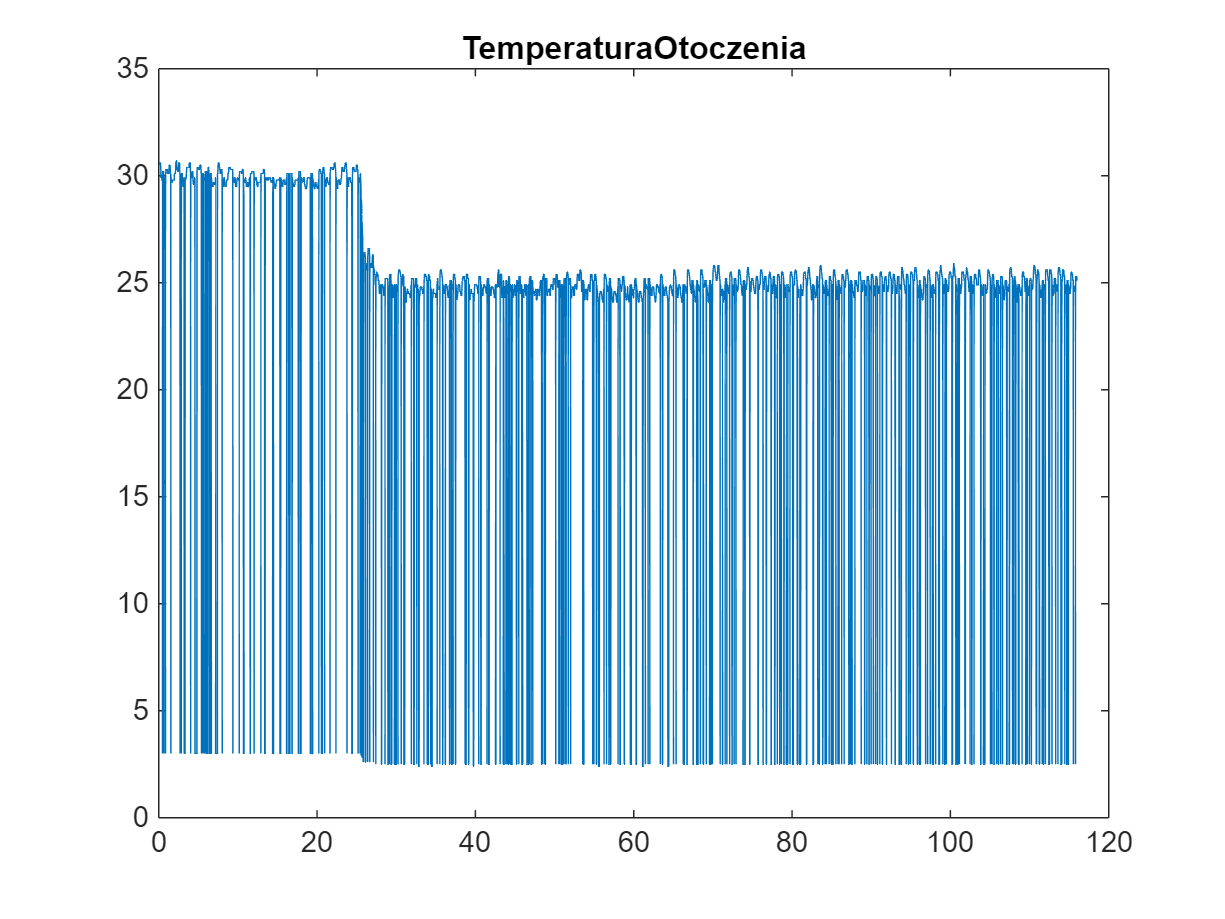

plot(t/(60*60),X(3,:))
title('TemperaturaOtoczenia')

We see measurement errors. We need to delete and interpolate values between 2 and 3.5 degrees

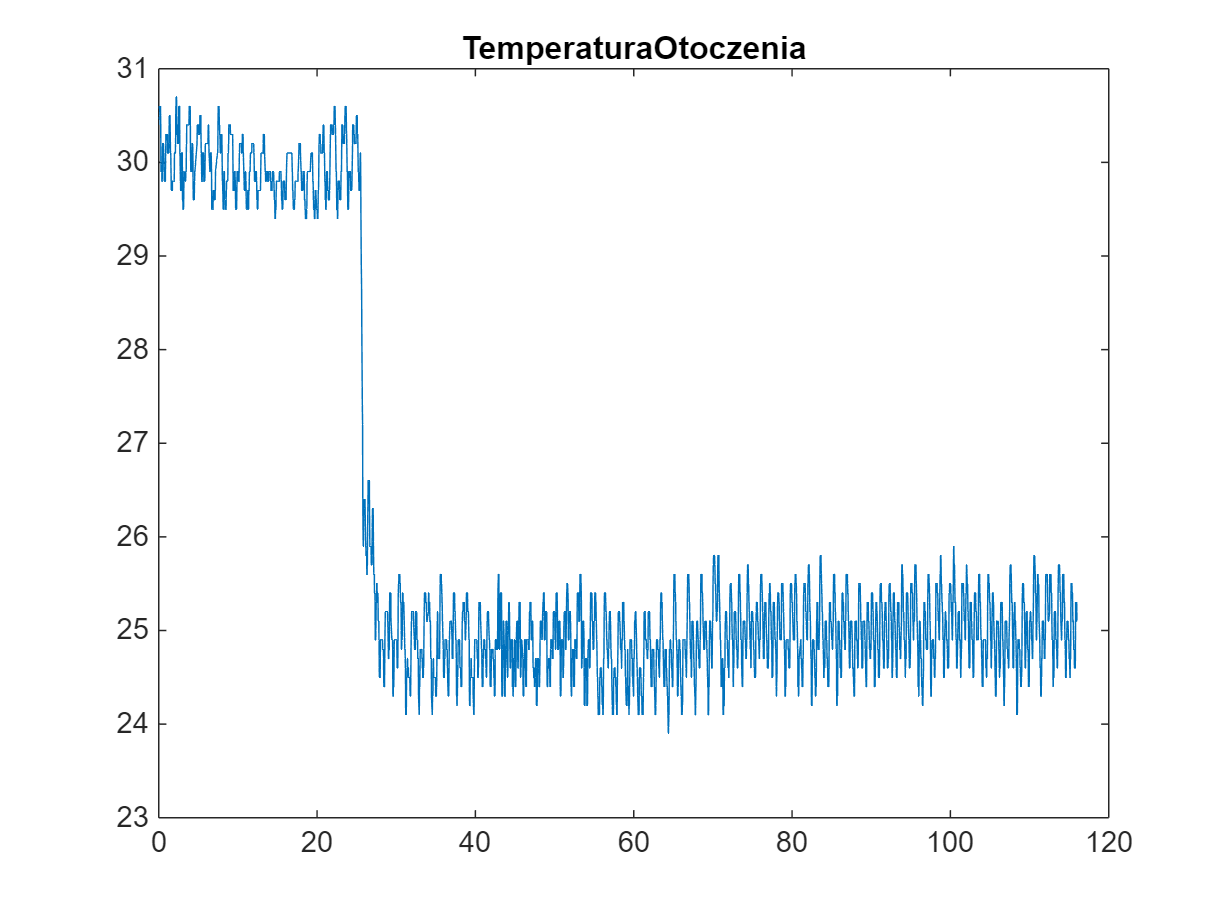

plot(t/(60*60),InterpolateData(X(3,:),[2,3.5],t_all))
title('TemperaturaOtoczenia')

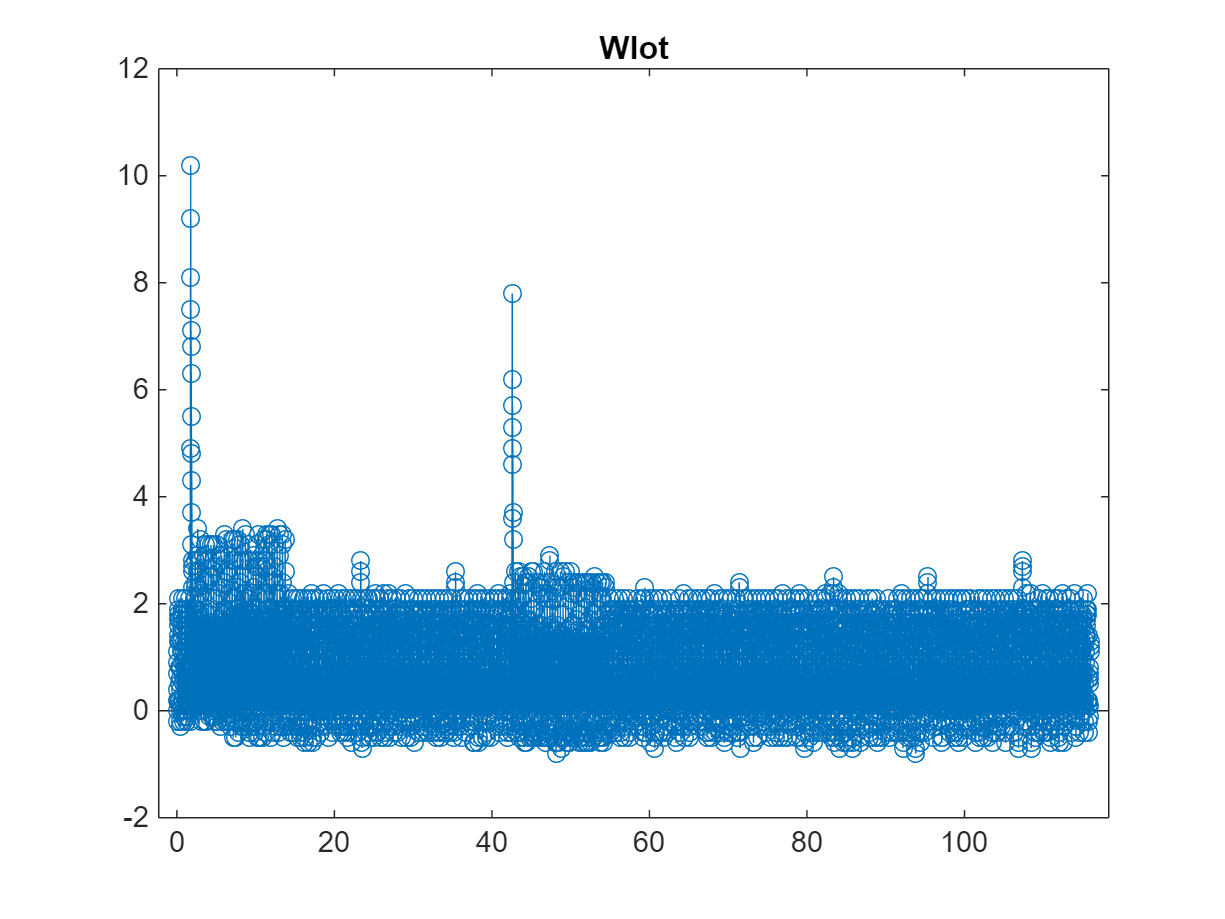

stem(t/(60*60),X(4,:))
title('Wlot')

errors between 0.05 and 0.15 degrees C

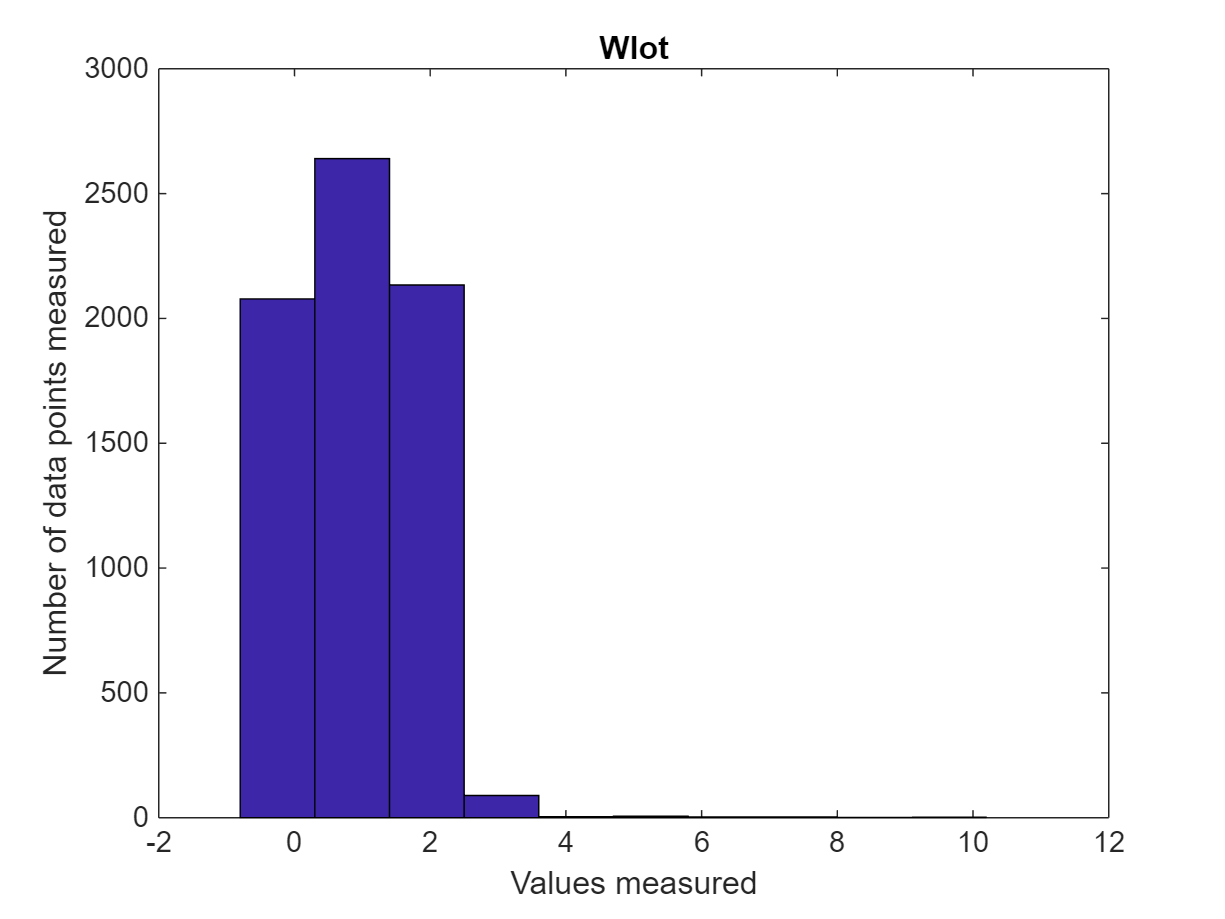

hist(X(4,:))
title('Wlot')
xlabel('Values measured')
ylabel('Number of data points measured')

test=InterpolateData(X(4,:),[0.005 0.15],t_all)

test =    -0.2000   -0.2000         0    0.2000    0.4000    0.7000    0.9000    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    0.2000    2.1000    0.2000    1.7000    1.3000    1.0500    0.8000    0.5000    0.2000         0   -0.2000   -0.3000   -0.2000         0    0.4000    0.6000    0.8000    0.9500    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    0.2000    2.1000    2.1000    1.8000    1.5000    1.1000    0.9000    0.6000    0.3000         0   -0.2000


test2=InterpolateData(test,[0.19 0.21],t_all)

test2 =    -0.2000   -0.2000         0    0.2000    0.4000    0.7000    0.9000    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    1.9000    1.7000    1.3000    1.0500    0.8000    0.5000    0.2500         0   -0.2000   -0.3000   -0.2000         0    0.4000    0.6000    0.8000    0.9500    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.1000    1.8000    1.5000    1.1000    0.9000    0.6000    0.3000         0   -0.2000


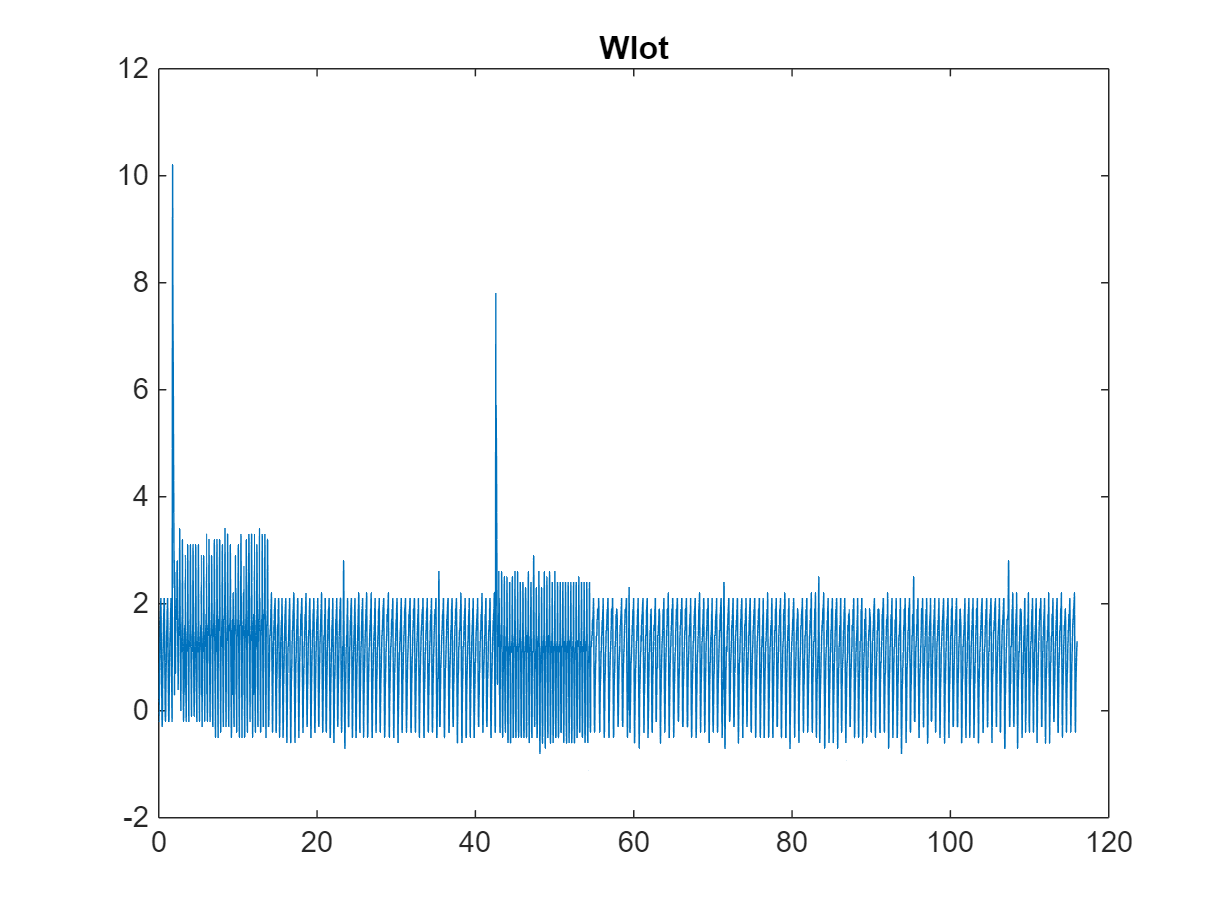

plot(t/(60*60),test2)
title('Wlot')

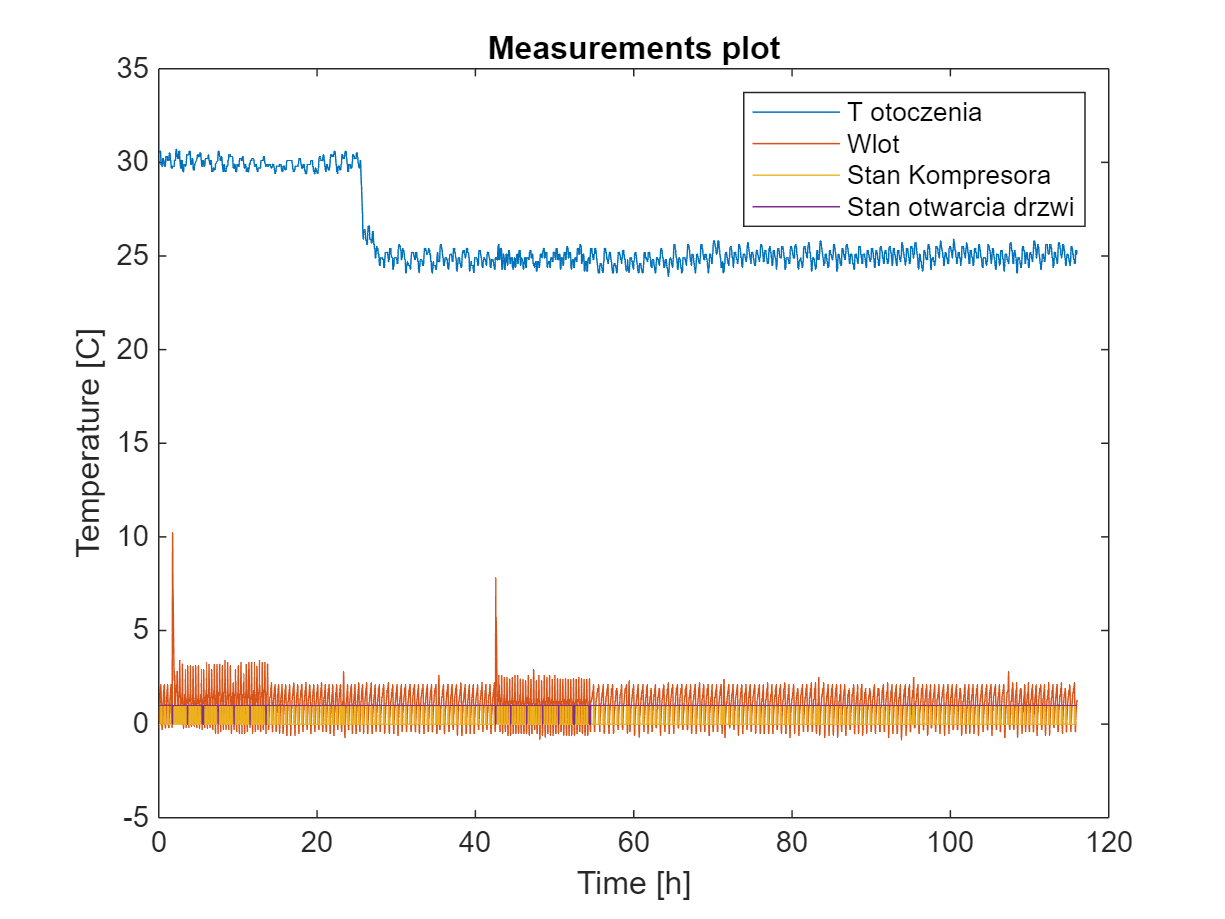

X_filtered=[InterpolateData(X(3,:),[2,3.5],t_all);test2];

plot(t/(60*60),X_filtered(1,:))
hold on
plot(t/(60*60),X_filtered(2,:))
plot(t/(60*60),X(1,:));
plot(t/(60*60),X(2,:));hold off
title('Measurements plot')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('T otoczenia','Wlot','Stan Kompresora','Stan otwarcia drzwi')

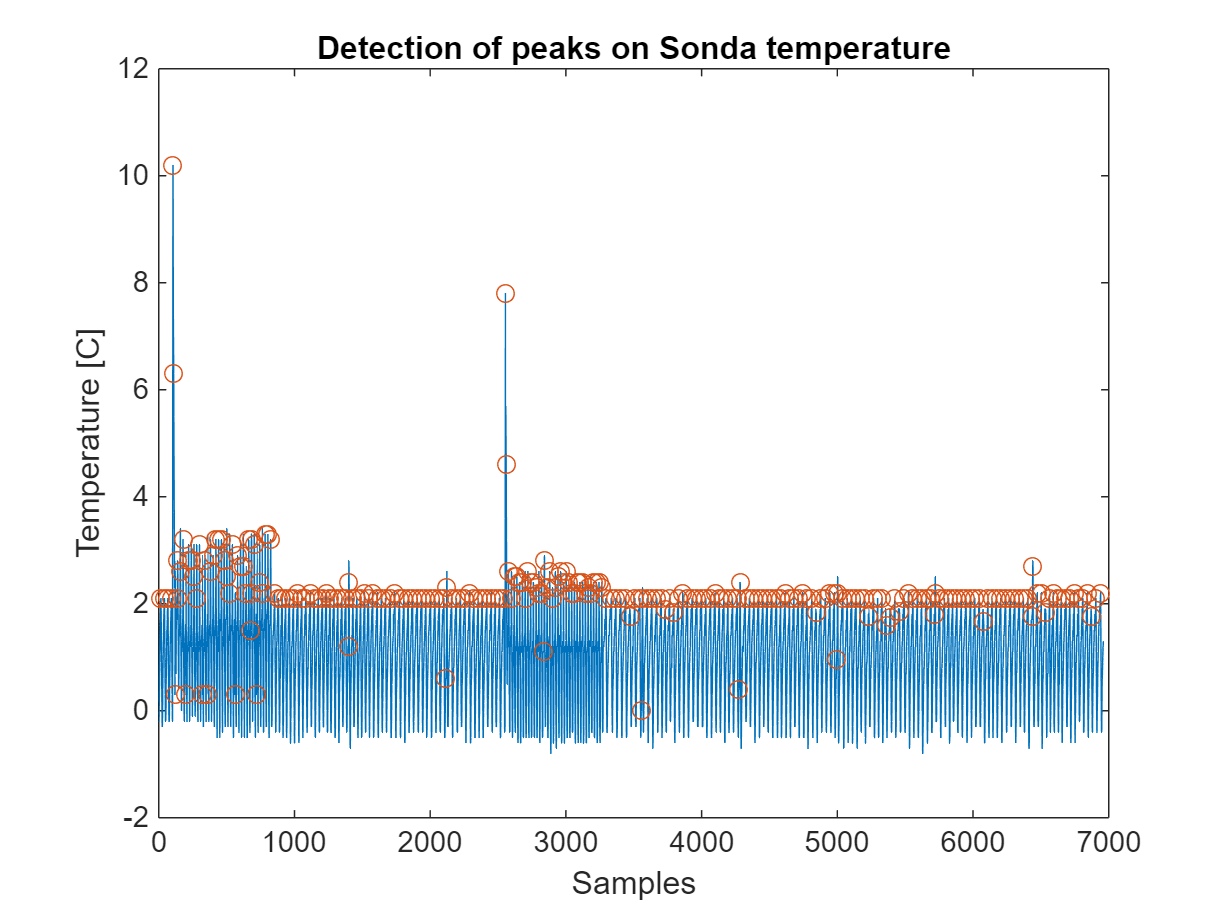

locs=compressorCycles(X(1,:));
x = FeatureExtract(X_filtered(2,:),locs);
plot((X_filtered(2,:)));hold on
plot(locs,(X_filtered(2,locs)),'o');hold off
title('Detection of peaks on Sonda temperature')
xlabel('Samples')
ylabel('Temperature [C]')

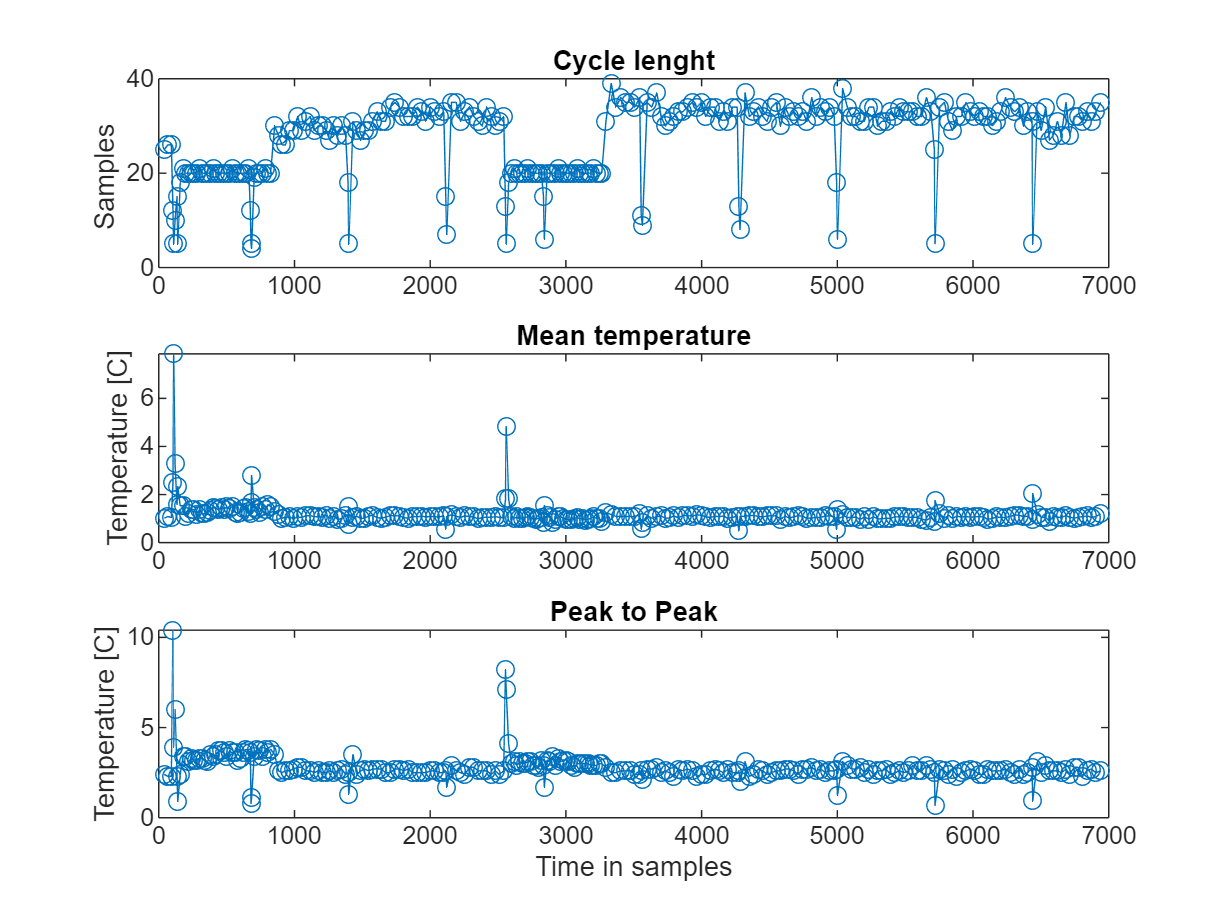

f1=zeros(1,length(locs)-1);
for i=1:length(locs)-1
    f1(i)=locs(i+1)-locs(i);
end
locs=locs(2:end);
figure 
subplot(311)
plot(locs,f1,'o-')
title('Cycle lenght')
ylabel('Samples ')
subplot(312)
plot(locs,x(3,:),'o-')
title('Mean temperature')
ylabel('Temperature [C]')
subplot(313)
plot(locs,x(1,:)-x(2,:),'o-')
title('Peak to Peak')
xlabel('Time in samples')
ylabel('Temperature [C]')

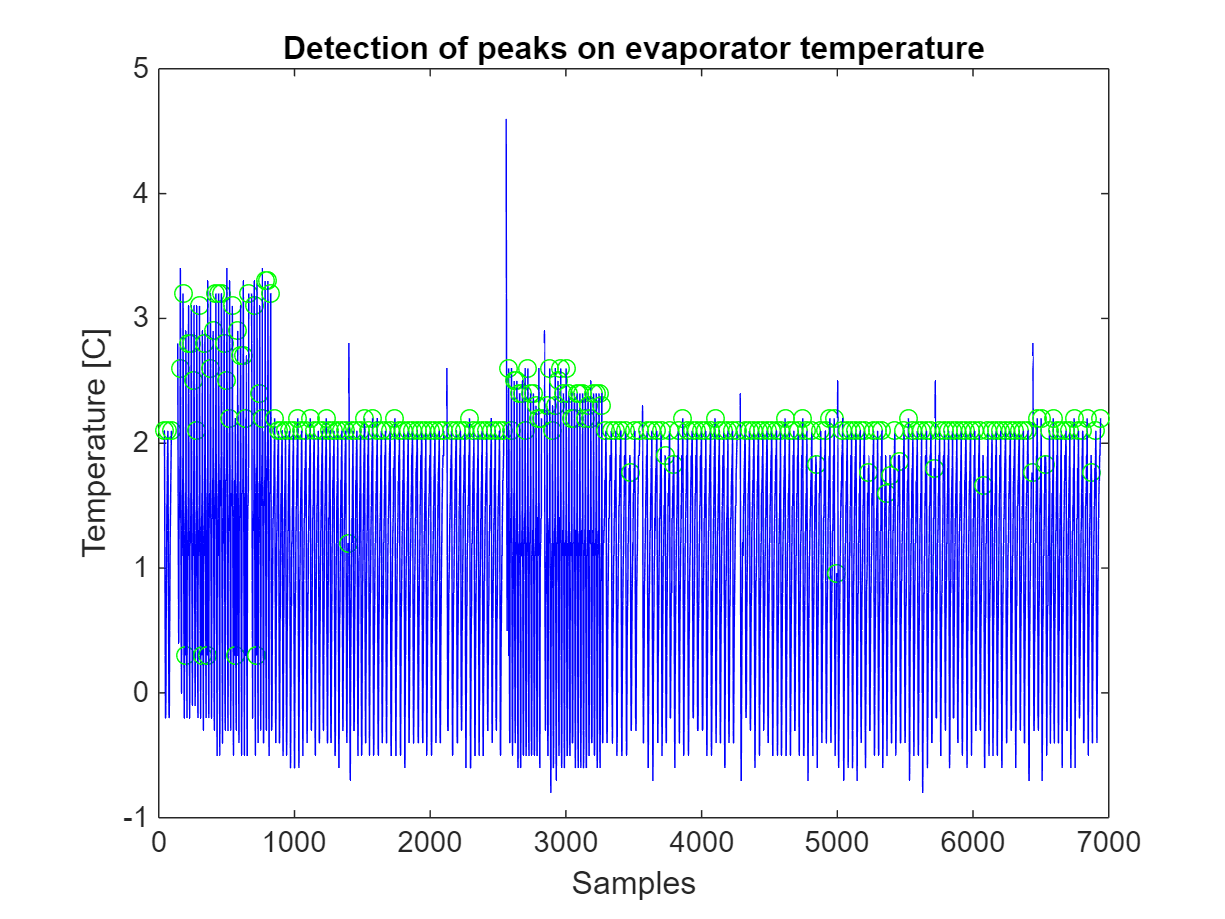

fridge_air_temp_p2p=x(1,:)-x(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
TF = isoutlier(f1);
% TF = isoutlier(fridge_air_temp_p2p);

plot(locs(1),(X_filtered(2,locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(x)
    
    if (TF(i)==0)
        plot(locs(i-1):locs(i),(X_filtered(2,locs(i-1):locs(i))),"Color",'blue');
        plot(locs(i),(X_filtered(2,locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},locs(i-1):locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')

Analysis of p2p suggest that the period of experiment was between sample 140 (pos indexContainer{2}(1)) and 824(pos indexContainer{3}(149))

Second period of experiment was: 2560 (pos indexContainer{6}(1)) and 3264 (pos indexContainer{7}(446))

% usableDataIndex{1}=indexContainer{1}; %We don't use the first one as it
% is too short
usableDataIndex{2-1}=indexContainer{3}(1,149:end);
usableDataIndex{3-1}=indexContainer{4};
usableDataIndex{4-1}=indexContainer{5};
usableDataIndex{5-1}=indexContainer{7}(446:end);
for i=6:10
usableDataIndex{i-1}=indexContainer{i+2};
end

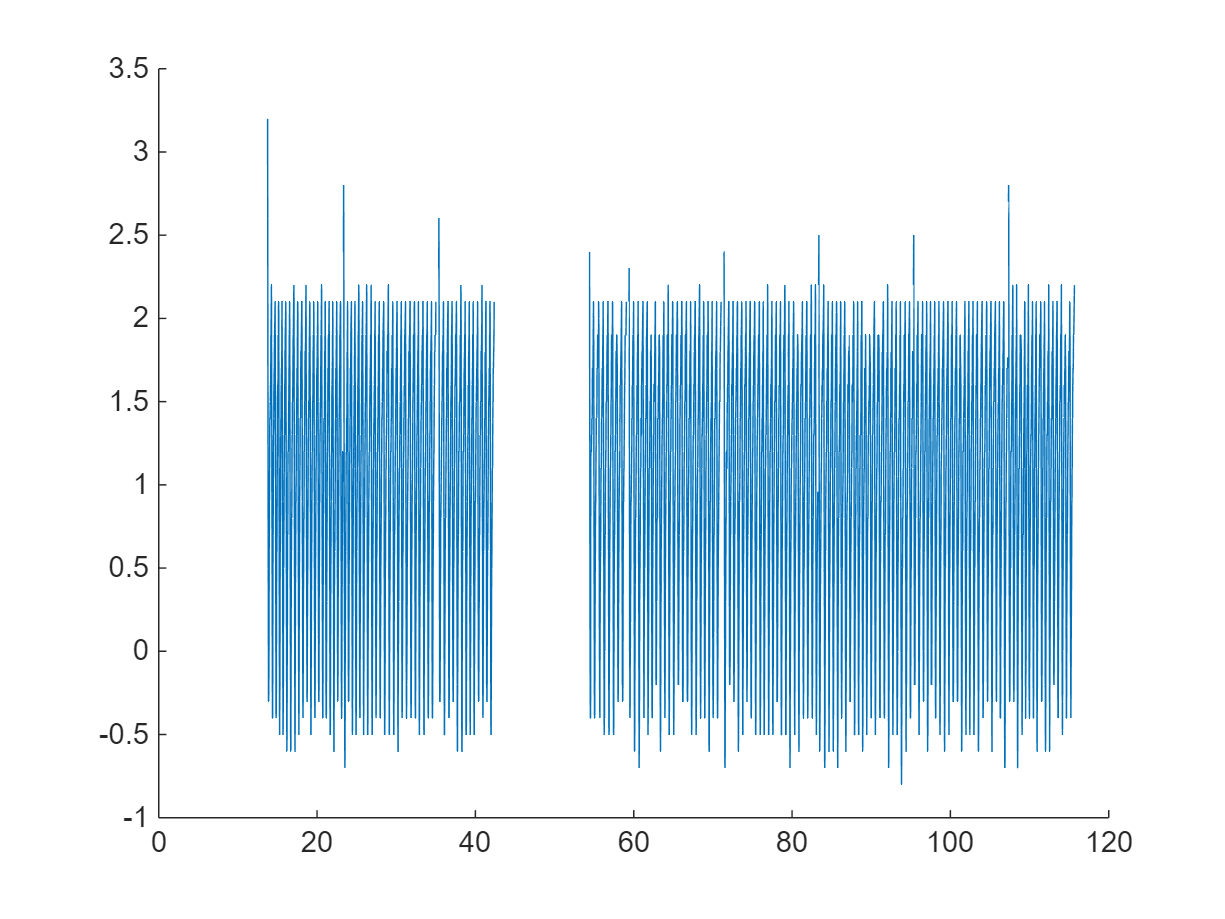

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X_filtered(2,usableDataIndex{i}),'Color','#0072BD')
end
hold off

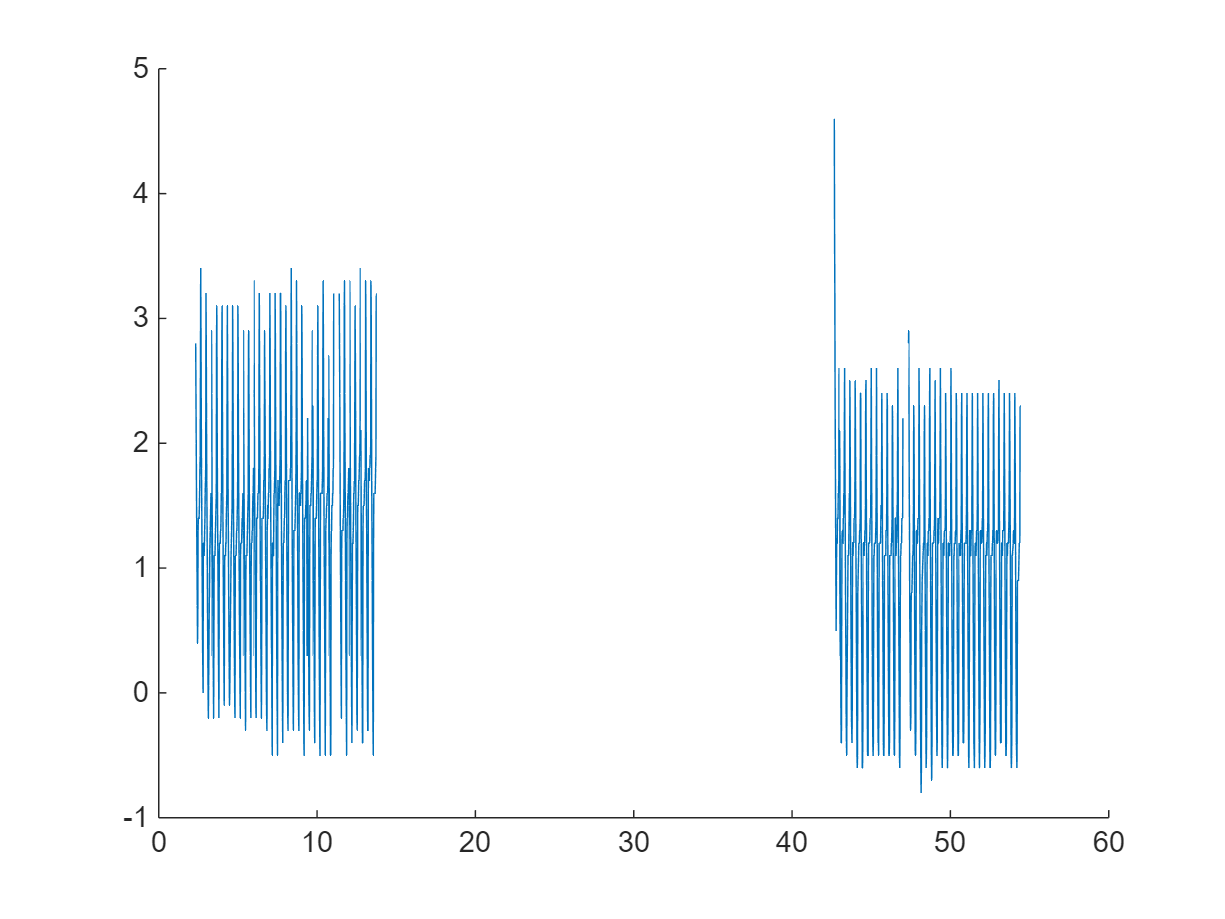


stat2ind={indexContainer{2};indexContainer{3}(1:148);indexContainer{6};indexContainer{7}(1:445)};

figure
hold on
for i = 1:length(stat2ind)
    plot(t(stat2ind{i})/(60*60),X_filtered(2,stat2ind{i}),'Color','#0072BD')
end
hold off

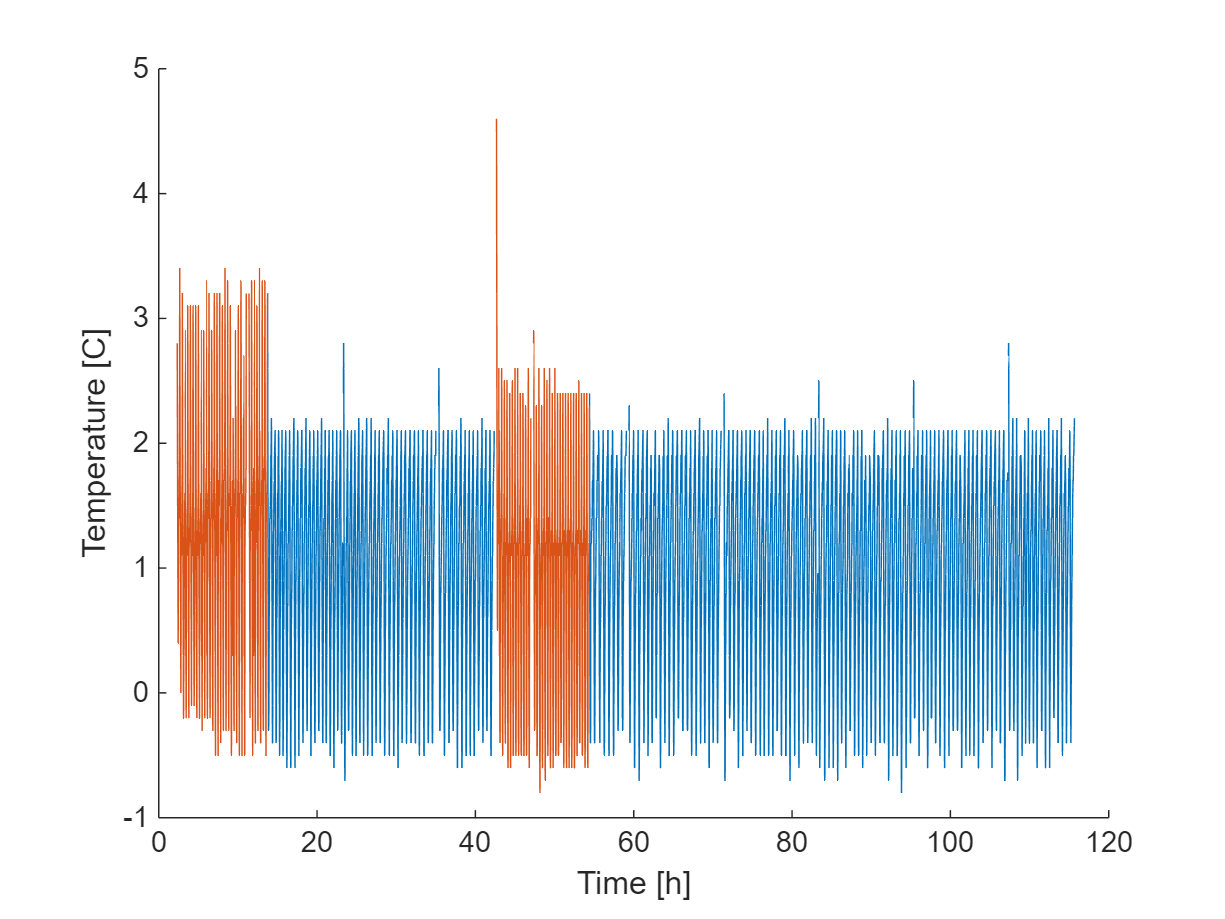

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X_filtered(2,usableDataIndex{i}),'Color','#0072BD')
end
for i = 1:length(stat2ind)
    plot(t(stat2ind{i})/(60*60),X_filtered(2,stat2ind{i}),'Color','#D95319')
end

hold off
xlabel('Time [h]')
ylabel('Temperature [C]')

totalLength=0;
for i = 1:length(usableDataIndex)
totalLength=totalLength+length(usableDataIndex{i});
end
for i = 1:length(usableDataIndex)
nTrainTimes(i)=round((length(usableDataIndex{i})/totalLength)*100);
end
nTrainTimes

nTrainTimes =     11    13     8     5    13    13    13    13     9


sum(nTrainTimes)

ans = 98

count=0;
y=cell(1,98);
params=cell(1,98);
rejestr1=zeros(1,98);
for i = 1:length(nTrainTimes)
for j=1:nTrainTimes(i)
    count=count+1;
    rejestr1(count)=i;
    % t_sim=T*(0:length(usableDataIndex{i})-1);
    % [y{count},params{count}]=GATrain(X(1,usableDataIndex{i}), X_filtered(1,usableDataIndex{i}),...
    %     t_sim, X_filtered(2,usableDataIndex{i}(1)), X_filtered(2,usableDataIndex{i}));
    usableDataIndexCellVector{count}=usableDataIndex{i};
    XCellVector{count}=X(1,usableDataIndex{i});
    X_filtered1CellVector{count}=X_filtered(1,usableDataIndex{i});
    X_filtered2CallVector{count}=X_filtered(2,usableDataIndex{i}(1));
    X_filtered22CallVector{count}=X_filtered(2,usableDataIndex{i});

end
end




count=0;
y=cell(1,98);
params=cell(1,98);

load Experiment2Results

% parfor i=1:length(usableDataIndexCellVector)
% % parfor i=1:2
%     t_sim=T*(0:length(usableDataIndexCellVector{i})-1);
%     [y{i},params{i}]=GATrain(XCellVector{i}, X_filtered1CellVector{i},...
%         t_sim, X_filtered2CallVector{i}, X_filtered22CallVector{i});
% end



% save Experiment2Results2 y params

y1=y;
params1=params;

% i=1;
% for count = 1:100
% % for i = 1:3
%     if count>50
%         i=2;
%     end
%     rejestr(count)=i;
%     t_sim=T*(0:length(stat2ind{i})-1);
%     % [y{reps},params{reps}]=GATrain(X(1,stat2ind{i}), X_filtered(1,stat2ind{i}),...
%     %     t_sim, X_filtered(2,stat2ind{i}(1)), X_filtered(2,stat2ind{i}));
%     stat2indCellVector{count}=stat2ind{i};
%     XCellVector2{count}=X(1,stat2ind{i});
%     X_filtered1CellVector2{count}=X_filtered(1,stat2ind{i});
%     X_filtered2CallVector2{count}=X_filtered(2,stat2ind{i}(1));
%     X_filtered22CallVector2{count}=X_filtered(2,stat2ind{i});
% end
clear y params
y=cell(1,100);
params=cell(1,100);

load Experiment2Results2ndSet.mat

% parfor i=1:length(stat2indCellVector)
% % parfor i=1:2
% 
%     t_sim=T*(0:length(stat2indCellVector{i})-1);
%     [y{i},params{i}]=GATrain(XCellVector2{i}, X_filtered1CellVector2{i},...
%         t_sim, X_filtered2CallVector2{i}, X_filtered22CallVector2{i});
% end
   
% save Experiment2Results2ndSet2 y params

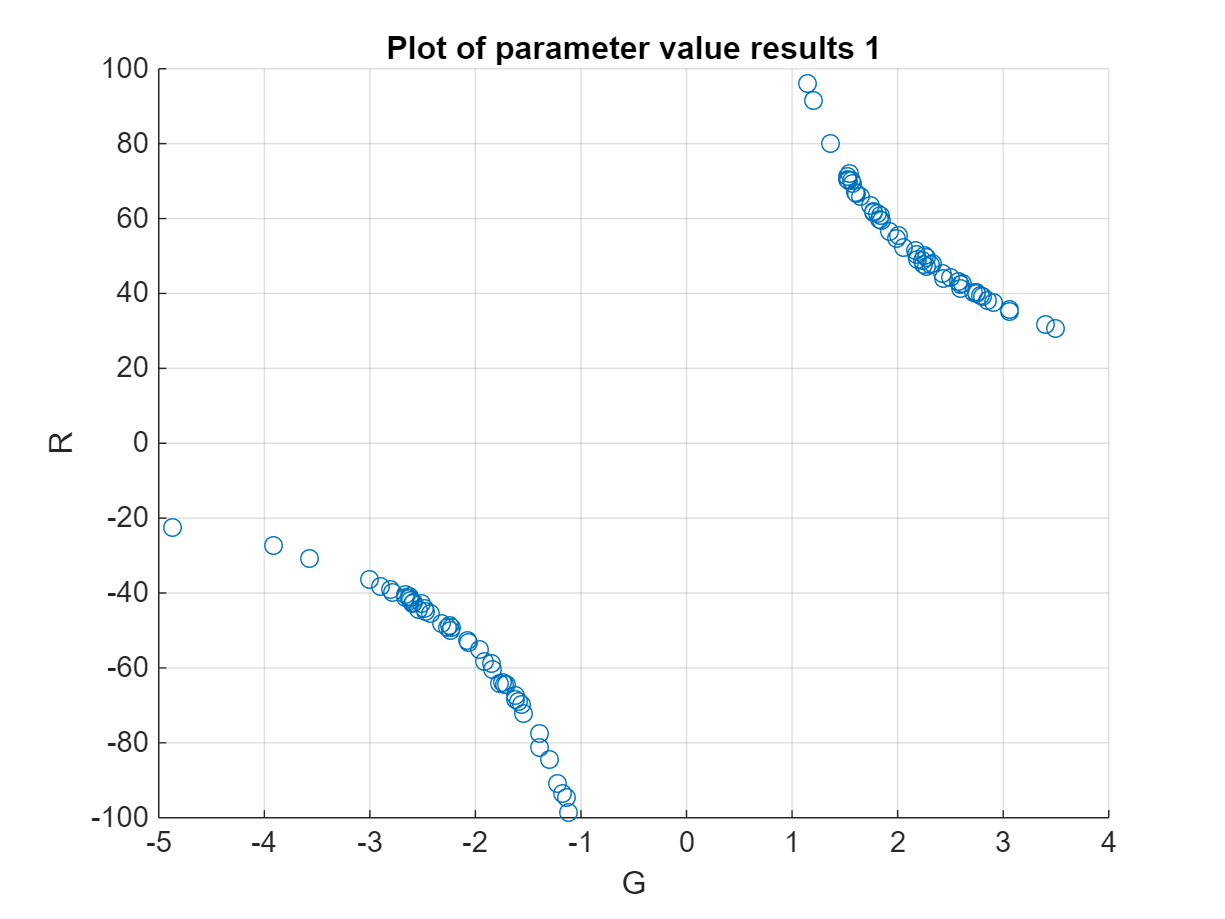

for i = 1:length(params1)
resu1(i,:)=params1{i};
end


figure
plot3(resu1(:,1),resu1(:,2),resu1(:,3),'o');
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results 1')
% view(0,0)
view(0,90)

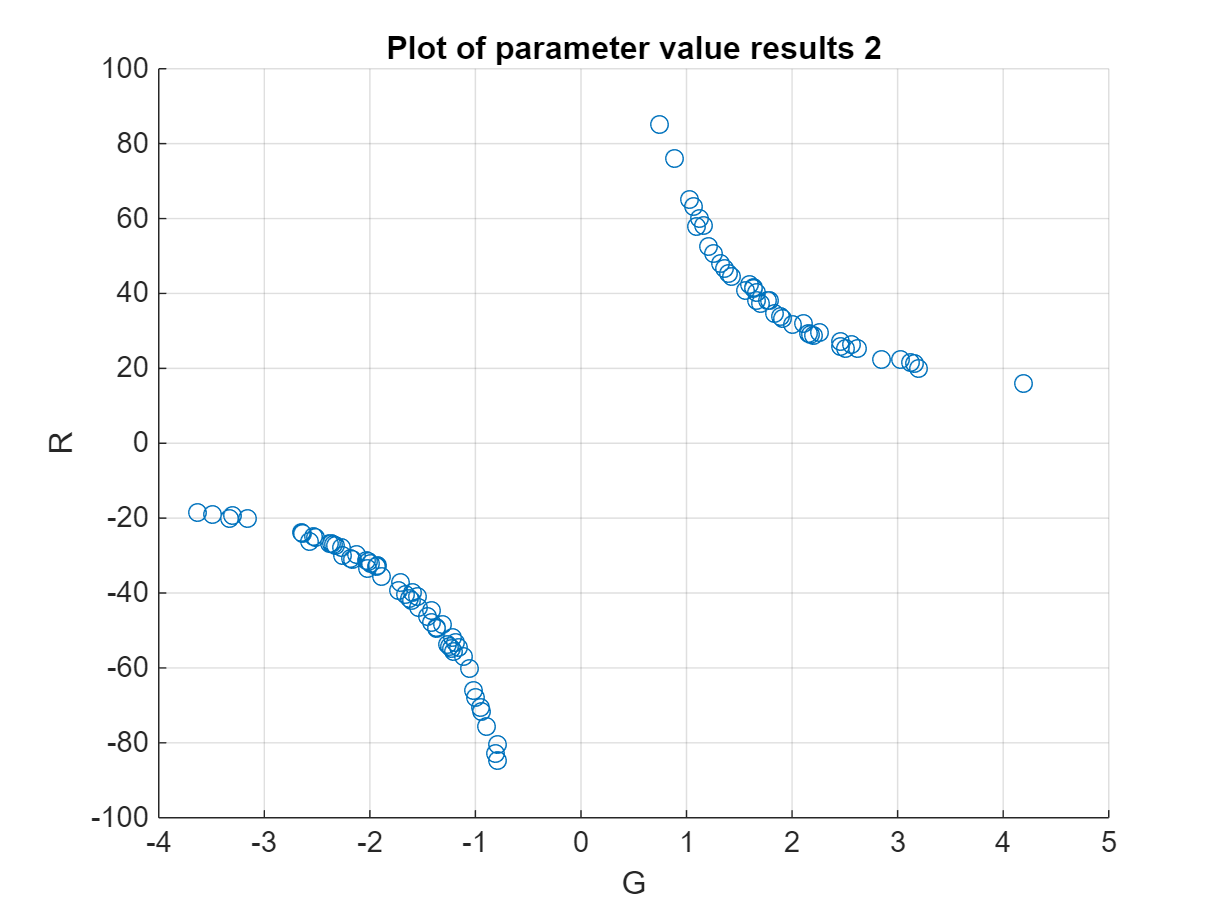

for i = 1:length(params)
resu(i,:)=params{i};
end


figure
plot3(resu(:,1),resu(:,2),resu(:,3),'o');
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results 2')
% view(0,0)
view(0,90)

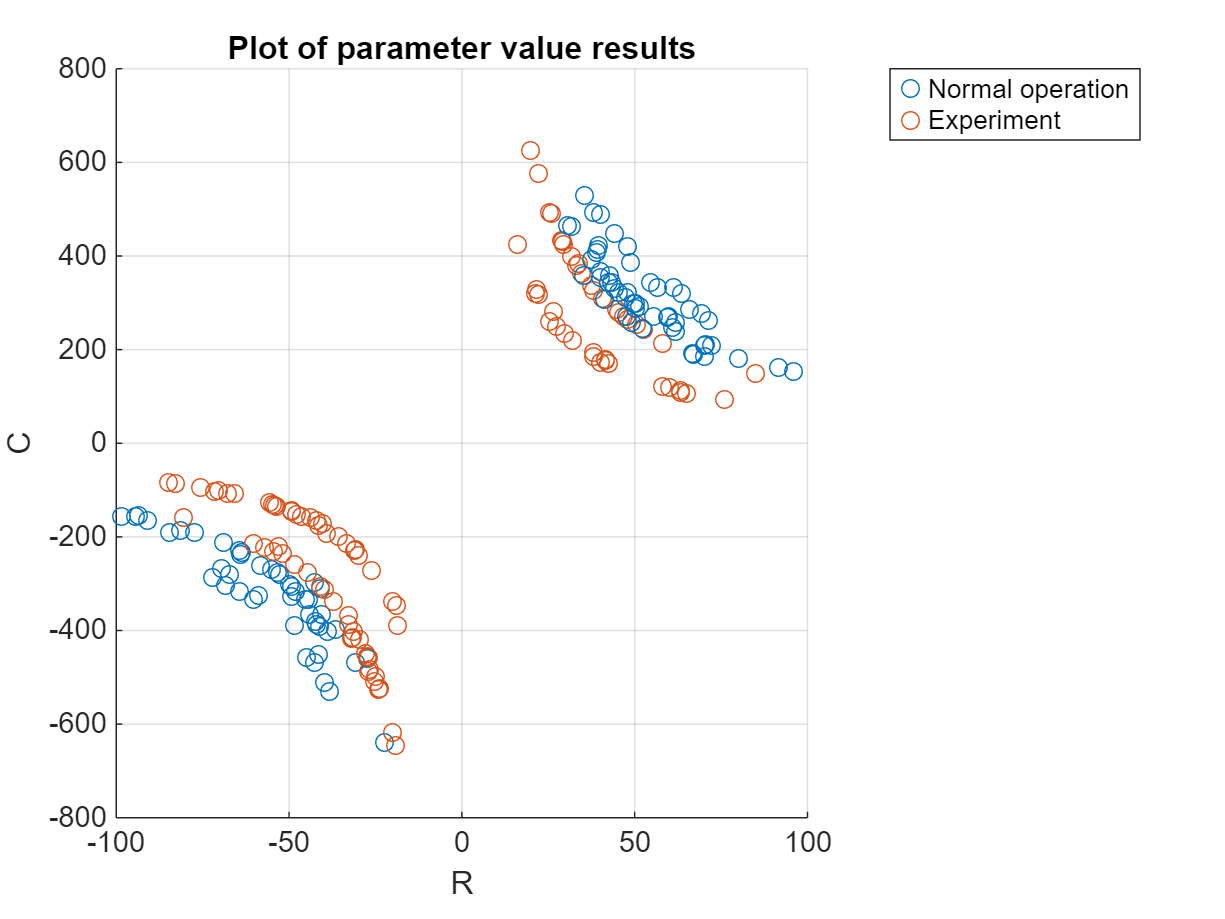

figure
plot3(resu1(:,1),resu1(:,2),resu1(:,3),'o');hold on
plot3(resu(:,1),resu(:,2),resu(:,3),'o');hold off
legend('Normal operation','Experiment')
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results')
% view(0,0)
% view(0,90)
view(90,0)